# Eloレーティングの計算サンプル

小中英嗣「科学で迫る勝敗の法則」

https://gihyo.jp/book/2024/978-4-297-13927-8

p.151-

clear;
clc;
close all;


csvファイルを読み込む

tbl=readtable('JResult2021.csv');
tbl.Category=categorical(tbl.Category);


J1の試合のみ抽出

tbl_J1=tbl(tbl.Category=='Ｊ１',:)

tbl_J1 = 380×14 table
    Year    Category        MatchSec           Date       DayOfWeek        HomeE           HomeJ           AwayE           AwayJ       HomeGoals    AwayGoals    MatchID       Venue       Attendance
    ____    ________    ________________    __________    _________    ______________    __________    ______________    __________    _________    _________    _______    ___________    __________

    2021      Ｊ１      {'第１節第１日'  }     2021/02/26     {'金'}      {'kawasakif' }    {'川崎Ｆ' }    {'yokohamafm'}    {'横浜FM'}         2            0         24974     {'等々力'  }       4868   
    2021      Ｊ１      {'第１節第２日'  }     2021/02/27     {'土'}      {'urawa'     }    {'浦和'  }     {'ftokyo'    }    {'FC東京'}        1            1         24976     {'埼玉'   }        4943   
    2021      Ｊ１      {'第１節第２日'  }     2021/02/27     {'土'}      {'sapporo'   }    {'札幌'  }     {'yokohamafc'}    {'横浜FC'}        5            1         24975     {'札幌ド'  }       11897   
    2021      Ｊ１  

チーム名を抽出する

teamNames=unique([tbl_J1.HomeE;tbl_J1.AwayE]);
tbl_J1.HomeE=categorical(tbl_J1.HomeE, teamNames);
tbl_J1.AwayE=categorical(tbl_J1.AwayE, teamNames);


Eloレーティングの計算

r=zeros(size(teamNames));
K=16;
for n1=1:size(tbl_J1,1)
    tiNum=find(teamNames==tbl_J1.HomeE(n1));
    tjNum=find(teamNames==tbl_J1.AwayE(n1));
    ri=r(tiNum);
    rj=r(tjNum);
    rDiff=ri-rj;
    wHat_ij=1/(1+10^(-rDiff/400));
    w_ij=1*(tbl_J1.HomeGoals(n1)>tbl_J1.AwayGoals(n1)) ...
        +0.5*(tbl_J1.HomeGoals(n1)==tbl_J1.AwayGoals(n1));
    r(tiNum)=ri+K*(w_ij-wHat_ij);
    r(tjNum)=rj-K*(w_ij-wHat_ij);
end


レーティング順に表示

tbl_teams=table();
tbl_teams=addvars(tbl_teams, teamNames, 'NewVariableNames','TeamE');
tbl_teams.TeamE=categorical(tbl_teams.TeamE);
tbl_teams=addvars(tbl_teams, r, 'NewVariableNames','Rating');
tbl_teams=sortrows(tbl_teams,"Rating",'descend');
tbl_teams=addvars(tbl_teams, (1:size(teamNames,1))', 'NewVariableNames','RankByRating');
tbl_teams

tbl_teams = 20×3 table
      TeamE       Rating     RankByRating
    __________    _______    ____________

    kawasakif      132.99          1     
    yokohamafm     82.997          2     
    kobe           78.612          3     
    kashima        63.278          4     
    nagoya         41.226          5     
    urawa          38.989          6     
    tosu           16.686          7     
    fukuoka        8.7633          8     
    ftokyo         -4.778          9     
    sapporo       -6.7662         10     
    hiroshima      -13.55         11     
    cosaka        -19.566         12     
    shimizu       -24.382         13     
    gosaka        -27.296         14     
    shonan        -41.805         15     
    kashiwa       -45.402         16     


横棒グラフで図示

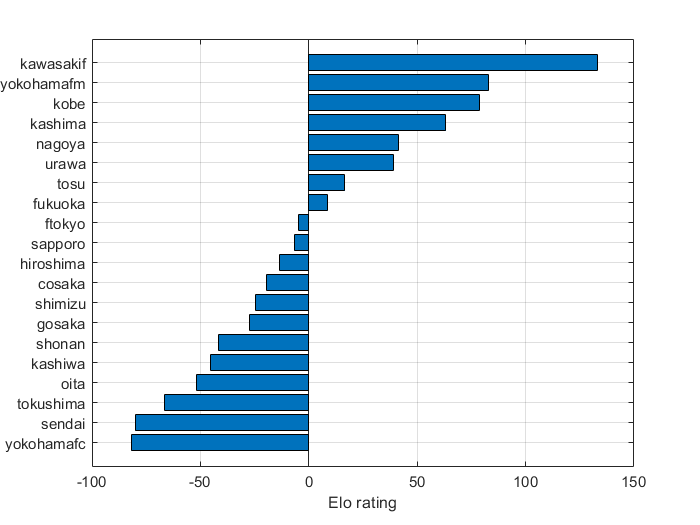

figure;
barh(tbl_teams.Rating);
grid on;
set(gca,'ydir','reverse','fontname','Arial');
yticks(1:size(teamNames,1));
yticklabels(tbl_teams.TeamE);
xlabel('Elo rating');
exportgraphics(gcf,'EloRatingSample.pdf');